# Flux Balance Analysis (examples and answers)

## Author(s): Ronan M.T. Fleming, Leiden University 

## Reviewer(s):

## INTRODUCTION

In this tutorial, Flux Balance Analysis (FBA) is introduced using the E. coli core model, with functions in the COBRA Toolbox v3.0 [2].  

Flux balance analysis is a solution to the optimisation problem


$$
\begin{array}{ll}
\textrm{max} & c^{T}v\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u
\end{array}
\end{equation}$$


where $c$ is a vector of linear objective coefficients, $S$ is an m times n matrix of stoichiometric coefficients for m molecular species involved in n reactions. $l\;\textrm{and}\;u\;$are n times 1 vectors that are the lower and upper bounds on the n times 1 variable vector $v\;$of reaction rates (fluxes). The optimal objective value is $c^{T}v^{\star}$  is always unique, but the optimal vector $v^{\star}$ is usually not unique.

In summary, the data is {c,S,l,u} and the variable being optimised is v.

## TIMING

*< 1 hrs*

## E. coli core model

A map of the E. coli core model is shown in Figure 1. 

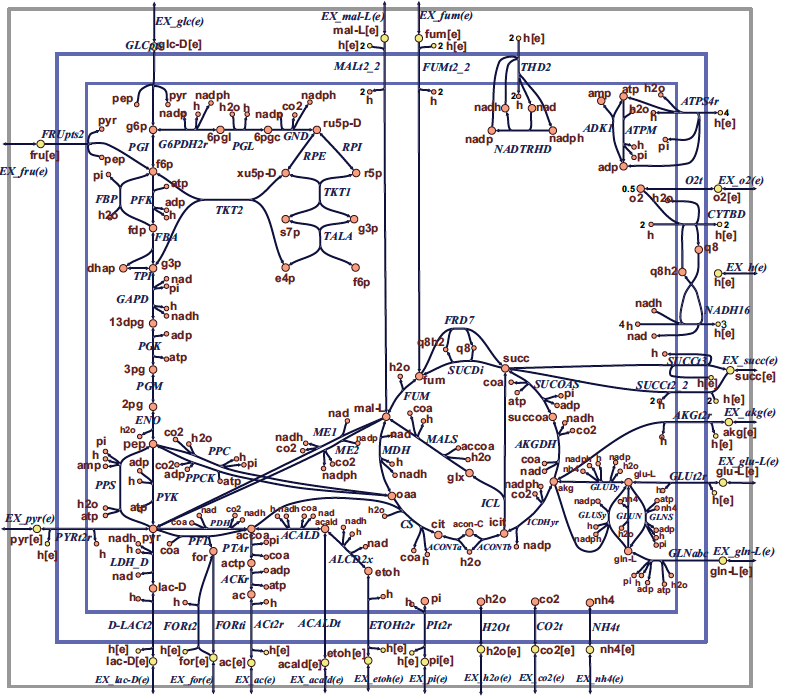

**Figure 1**  **Map of the core E. coli metabolic network. ** Orange circles represent cytosolic metabolites, yellow circles represent extracellular metabolites, and the blue arrows represent reactions.  Reaction name abbreviations are uppercase (blue) and metabolite name abbreviations are lowercase (rust colour).  This flux map was drawn using SimPheny and edited for clarity with Adobe Illustrator. 

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most appropriate way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

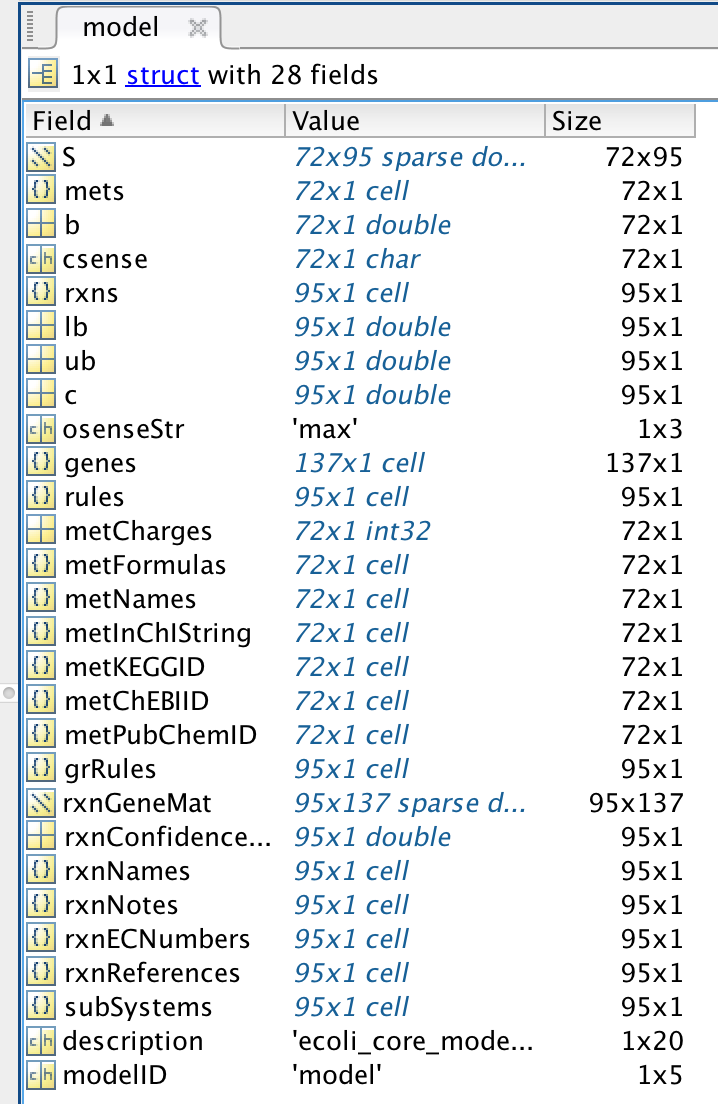

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

printConstraints(model,-1000,1000)

MinConstraints:
ATPM	8.39
EX_glc(e)	-10
maxConstraints:


## Example 1: Calculating growth rates

Growth of E. coli on glucose can be simulated under aerobic conditions.  

#### What is the growth rate of *E. coli *on glucose (uptake rate = 18.5 mmol/gDW/h) under aerobic and anaerobic conditions?  

#### Hint: `changeRxnBounds`, `changeObjective`, `optimizeCbModel`, `printFluxVector`

To set the maximum glucose uptake rate to 18.5 mmol gDW-1 hr-1 (millimoles per gram dry cell weight per hour, the default flux units used in the COBRA Toolbox), enter:

model = changeRxnBounds(model,'EX_glc(e)',-18.5,'l');

This changes the lower bound ('l') of the glucose exchange reaction to -18.5, a biologically realistic uptake rate.  By convention, exchange reactions are written as export reactions (e.g. ‘glc[e] <==>’), so import of a metabolite is a negative flux.  

To allow unlimited oxygen uptake, enter:

model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');

By setting the lower bound of the oxygen uptake reaction to such a large number, it is practically unbounded.  Next, to ensure that the biomass reaction is set as the objective function, enter:

model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');

The default behaviour of the function `optimizeCbModel` is to conduct flux balance analysis on a `model` structure.  This function is the most powerful function in the COBRA toolbox and has many optional inputs and outputs but for a straightforward flux balance analysis, the following fields of a model are the required input:

%    model:             (the following fields are required - others can be supplied)
%
%                         * S  - `m x 1` Stoichiometric matrix
%                         * c  - `n x 1` Linear objective coefficients
%                         * lb - `n x 1` Lower bounds
%                         * ub - `n x 1` Upper bounds

To perform FBA with maximization of the biomass reaction as the objective, enter:

FBAsolution = optimizeCbModel(model,'max')

FBAsolution = struct with fields:
         full: [95×1 double]
          obj: 1.6531
        rcost: [95×1 double]
         dual: [72×1 double]
        slack: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0280
        basis: []
            f: 1.6531
            x: [95×1 double]
            v: [95×1 double]
            w: [95×1 double]
            y: [72×1 double]
            s: [72×1 double]


#### What are the main fields to check in the FBAsolution structure?

#### Hint: `help optimizeCbModel`

There are many outputs fields in the `FBAsolution` structure, but the key ones for any FBA solution are

%    solution:       solution object:
%             * f - Objective value
%             * v - Reaction rates (Optimal primal variable, legacy FBAsolution.x)
%             * stat - Solver status in standardized form

FBAsolution.f  gives the value of the objective function, which should be 1.6531 mmol gDW-1 hr-1 

FBAsolution.f

ans = 1.6531

This is the same as 

model.c'*FBAsolution.v

ans = 1.6531

This means that the model predicts a growth rate of 1.6531 hr-1.  Inspection of the flux distribution vector FBAsolution.v shows that there is high flux in the glycolysis, pentose phosphate, TCA cycle, and oxidative phosphorylation pathways, and that no organic by-products are secreted (Figure 2a).

`FBAsolution.v` gives the optimal flux vector

FBAsolution.v

ans =          0
         0
    0.0000
   10.3657
   10.3657
         0
         0
    8.5822
         0
         0


Inspection of the flux distribution is more convenient with the `printFluxVector` function

fluxData = FBAsolution.v;
nonZeroFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag)

ACONTa              	       10.37
ACONTb              	       10.37
AKGDH               	       8.582
ATPM                	        8.39
ATPS4r              	       80.61
Biomass_Ecoli_core_N(w/GAM)-Nmet2	       1.653
CO2t                	      -40.65
CS                  	       10.37
CYTBD               	       77.48
ENO                 	       26.84
EX_co2(e)           	       40.65
EX_glc(e)           	       -18.5
EX_h2o(e)           	       52.69
EX_h(e)             	       33.16
EX_nh4(e)           	      -9.014
EX_o2(e)            	      -38.74
EX_pi(e)            	      -6.081
FBA                 	       13.56
FUM                 	       8.582
G6PDH2r             	       9.881
GAPD                	       29.31
GLCpts              	        18.5
GLNS                	      0.4227
GLUDy               	      -8.591
GND                 	       9.881
H2Ot                	      -52.69
ICDHyr              	       10.37
MDH                 	       8.582
NADH16              	        68.9
N

#### What does FBAsolution.stat mean?

## Example 2: Display an optimal flux vector on a metabolic map

#### Which reactions/pathways are in use (look at the flux vector and flux map)?

#### Hint: `drawFlux`

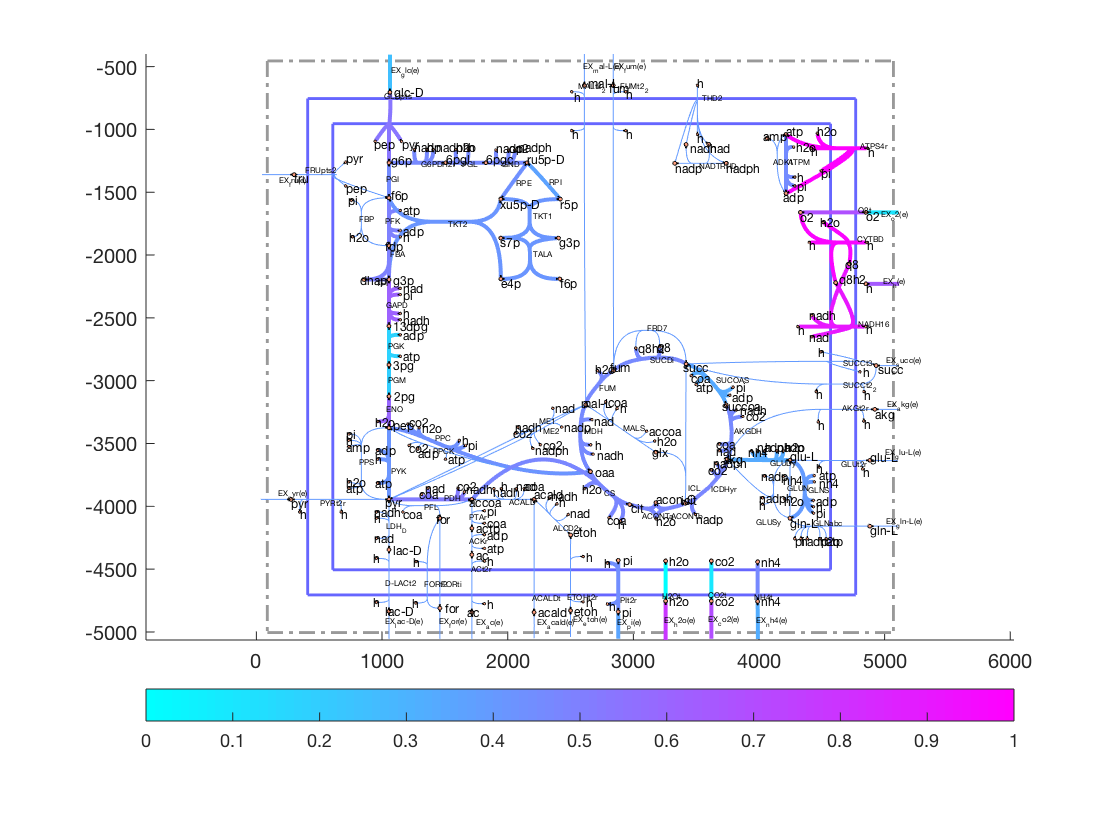

outputFormatOK = changeCbMapOutput('matlab');
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.v, options);

## Example 3:  Anerobic growth

Growth of E. coli on glucose can be simulated under anaerobic conditions.  

#### What is the optimal growth rate under anaerobic conditions?

#### Hint: changeRxnBounds

Next, the same simulation is performed under anaerobic conditions.  With the same model:

model = changeRxnBounds(model,'EX_o2(e)',0,'l');

The lower bound of the oxygen exchange reaction is now 0, so oxygen may not enter the system.  When optimizeCbModel is used as before, the resulting growth rate is now much lower, 0.4706 hr-1.  

FBAsolution2 = optimizeCbModel(model,'max');
FBAsolution2.f

ans = 0.4706

#### What reactions of oxidative phosphorylation are active in anaerobic conditions?

#### Hint: `printFluxVector` `drawFlux`

The flux distribution shows that oxidative phosphorylation is not used in these conditions, and that acetate, formate, and ethanol are produced by fermentation pathways (Figure 2b). Inspection of both flux vectors for comparison:

fluxData = [FBAsolution.v,FBAsolution2.v];
nonZeroFlag = 1;
excFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag, excFlag)

Biomass_Ecoli_core_N(w/GAM)-Nmet2	       1.653      0.4706
EX_ac(e)            	           0       15.17
EX_co2(e)           	       40.65     -0.8408
EX_etoh(e)          	           0       14.67
EX_for(e)           	           0       32.12
EX_glc(e)           	       -18.5       -18.5
EX_h2o(e)           	       52.69      -12.09
EX_h(e)             	       33.16       56.73
EX_nh4(e)           	      -9.014      -2.566
EX_o2(e)            	      -38.74           0
EX_pi(e)            	      -6.081      -1.731


drawFlux(map, model, FBAsolution2.v, options);

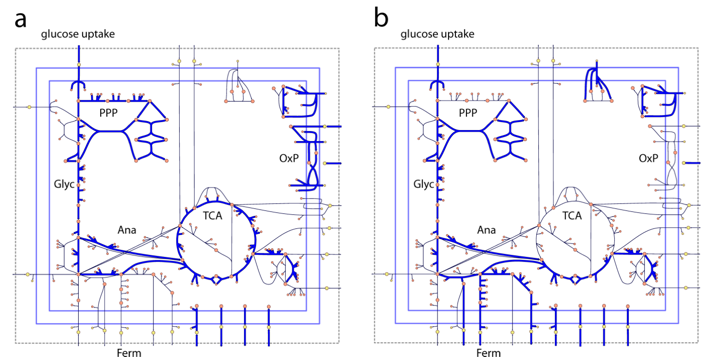

**Figure 2 ** Flux vectors computed by FBA can be visualized on network maps.  In these two examples, the thick blue arrows represent reactions carrying flux, and the thin black arrows represent unused reactions.  These maps show the state of the E. coli core model with maximum growth rate as the objective (Z) under aerobic (a) and anaerobic (b) conditions.  Reactions that are in use have thick blue arrows, while reactions that carry 0 flux have thin black arrows. The metabolic pathways shown in these maps are glycolysis (Glyc), pentose phosphate pathway (PPP), TCA cycle (TCA), oxidative phosphorylation (OxP), anaplerotic reactions (Ana), and fermentation pathways (Ferm). 

## Example 4:  Growth on alternate substrates

Just as FBA was used to calculate growth rates of E. coli on glucose, it can also be used to simulate growth on other substrates.  The core E. coli model contains exchange reactions for 13 different organic compounds, each of which can be used as the sole carbon source under aerobic conditions. 

#### What is the growth rate of *E. coli *on succinate?

#### Hint: `changeRxnBounds`

Before trying out new boundary conditions on a model, make sure one's starting point is appropriate.

model = modelOri;

For example, to simulate growth on succinate instead of glucose, first use the changeRxnBounds function to set the lower bound of the glucose exchange reaction (EX_glc(e)) to 0.  

model = changeRxnBounds(model,'EX_glc(e)',0,'l');

Then use changeRxnBounds to set the lower bound of the succinate exchange reaction (EX_succ(e)) to -20 mmol gDW-1 hr-1 (an arbitrary uptake rate).  

model = changeRxnBounds(model,'EX_succ(e)',-20,'l');

As in the glucose examples, make sure that the biomass reaction is set as the objective (the function checkObjective can be used to identify the objective reaction(s)), 

checkObjective(model);

summaryT = 23×5 table
    Coefficient    Metabolite    metID                Reaction                 RxnID
    ___________    __________    _____    _________________________________    _____

       -1.496       3pg[c]         3      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
      -3.7478       accoa[c]      10      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
        59.81       adp[c]        13      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       4.1182       akg[c]        14      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       -59.81       atp[c]        17      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       3.7478       coa[c]        21      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       -0.361       e4p[c]        23      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
      -0.0709       f6p[c]        26      

Use optimizeCbModel to perform FBA, then the growth rate, given by FBAsolution.f, will be 0.8401 hr-1. 

FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = 0.8401

Growth can also be simulated under anaerobic conditions with any substrate by using changeRxnBounds to set the lower bound of the oxygen exchange reaction (EX_o2(e)) to 0 mmol gDW-1 hr-1, so no oxygen can enter the system.  When this constraint is applied and succinate is the only organic substrate, optimizeCbModel returns a growth rate of 0 hr-1

model = changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = 0

In this case, FBA predicts that growth is not possible on succinate under anaerobic conditions.  Because the maximum amount of ATP that can be produced from this amount of succinate is less than the minimum bound of 8.39 mmol gDW-1 hr 1 of the ATP maintenance reaction, ATPM, there is no feasible solution.

## TROUBLESHOOTING

Although it does not happen often, there are many reasons why an FBA problem might not solve, so they are divided into three categories. 

%      solution.stat - Solver status in standardized form:
%                      * `-1` - No solution reported (timelimit, numerical problem etc)
%                      * `1` - Optimal solution
%                      * `2` - Unbounded solution
%                      * `0` - Infeasible

`solution.stat == 0`  means that the problem is overconstrainted and no feasible flux vector v exists. The constraints need to be relaxed before the problem will solve. See tutorial_relaxedFBA.mlx

`solution.stat = 2`  means that the problem is underconstrained to the extent that the possible optimal value of the objective is unbounded, that is infinity, or minus infinity. This means that extra constraints need to be added, e.g., lower and upper bounds on the reaction rates.

`solution.stat = 1`  means that the problem is more complicated than either of the above. It could be that the problem does, in principle, have a solution, but that the current solver cannot find one, so an industrial quality solver should be tested, e.g., gurobi. It could also mean that the FBA problem is poorly scaled so there are numerical problems solving it, or it could also be just slightly infeasible, in which case a higher precision solver will be required to solve the problem, e.g., a quadruple precision solver. The way each solver reports the nature of the problem varies between solvers, so checking `solution.origStat` against the documentation that comes with each solver is necessary to figure out what the potential solution is.

%    solution.stat - Solver status in standardized form:
%                      * `-1` - No solution reported (timelimit, numerical problem etc)
%                      * `1` - Optimal solution
%                      * `2` - Unbounded solution
%                      * `0` - Infeasible

## *Acknowledgments*

Part of this tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1. Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

2. Varma, A. & Palsson, B.O. Metabolic capabilities of Escherichia coli: I. Synthesis of biosynthetic precursors and cofactors. Journal of Theoretical Biology 165, 477-502 (1993).

3. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).